%% FINAL PROJECT CODE 
% By Aya Kanawati and Sarah Scioli 

close all 

**Modeling Lahar Flow Dynamics with a Nonlinear Advection Equation Using the Forward Euler Method **

Introduction  

Understanding critical hazards and predicting their characteristics is important in mitigating potential harm caused by such hazards. One such hazard is lahars, which are mixtures of water and pyroclastic debris that flow down volcanic slopes. The first large observed lahar occurred in New Zealand in 1953, which swept out and totaled a railroad right before the Wellington-Auckland Express was to travel across, killing 153 people. These lahars continue to prove a threat in New Zealand, with 13 observed lahars occurring between 1953-1977, with volumes averaging 500,000 $m^3
$ per lahar (Vignauz and Weir, 1990). As with the 1953 incident, these hazardous flows can cause catastrophic damage to infrastructure, furthering the potential loss of life. Hence, properly modeling these lahars is necessary for understanding and predicting their character as they sweep down slopes and mitigating their harms. 

One way lahar flow can be monitored is with the one dimensional nonlinear advection equation. This equation can be used to model the lahar thickness *h(x,t) *across a channel. The lahar flow is simulated based on the time and the distance traveled based on that time, and this governing differential equation is solved using the Forward Euler method. This model assumes that the lahar is wide and fast, moving down a shallow bed slope (Slingerland and Klump, 2011). Thus, the flow depends on the law of conservation of mass and the law of conservation of momentum. The advection equation is especially useful for modeling the law of conservation of momentum of an incompressible fluid mass, which, in this case, is the lahar parcel (Delden, 2020). 

Previous studies modeled lahar flows with simplified advection equations. However, this study aims to account for the non-linearity of lahar movement, using the model discussed by Slingerland and Krump. This is accounted for by incorporating a nonlinear velocity term within the advection equation and solving for the resulting partial differential equation using the Forward Euler method. By incorporating this nonlinear term, the model allows for a more realistic representation of lahar flow behavior, demonstrating the dynamical interactions of multiple parameters as they interact with the lahar over distance and time. 

Equations 

Because the lahar acts as a mass with a changing velocity, the model utilizes the law of conservation of mass and the law of conservation of momentum. In this, we also assume that (1) the lahar has a constant width; (2) the lahar does not add additional material to itself as it moves down its path; (3) the lahar flow works similarly to that of water; (4) the lahar has a constant bed slope; and (5) the drag coefficient of the flow is constant.  

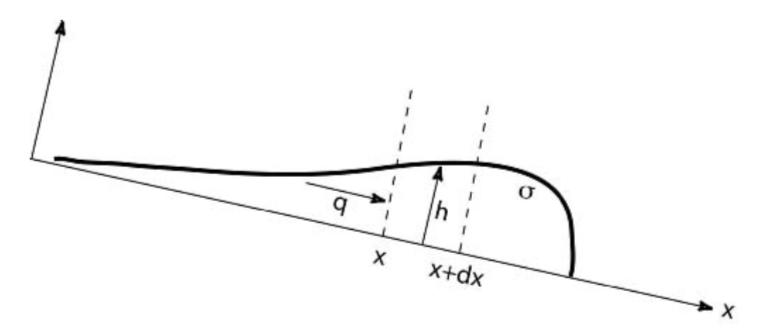

*Figure 1: Schematic of the lahar flow down a slope (Slingerland and Krump, 2011).*

To better understand this lahar rate using the Law of Conservation of Mass, the time rate of change of the mass of the lahar in the cell as shown in Figure 1, is equal to the mass’s rate of flow into and out of the cell. Hence, we come to the equation of: 

TROCM= MRI- MRO  				(1)

The mass in the cell is the cell volume Bhdx, where B is the unit width (in meters), and h is the height of the lahar in meters, multiplied by the bulk density  of the lahar. The volumetric rate which the lahar flows into the cell through the face at* x* is the volumetric flux per unit width, *q*, multiplied by the per unit width and by its bulk density. The mass rate out of the cell, at *x+dx*, is obtained using a Taylor Series. Hence, we get the equation: 

$\frac{\partial \sigma Bhdx}{\partial t} = \sigma qB-(\sigma q B- \frac{\partial \sigma B}{\partial x}dx)
$		 (2) 

Because the model assumes the width x and the bulk density  do not vary in space in time, the governing equation becomes: 	

$\frac{\partial h${$\frac{\partial h}{\partial t } + \frac {\partial}{\partial x} (q) = 0
$ 	 			        (3)

Where q is related to the flow velocity *u* and the lahar’s thickness *h*.

The law of conservation of momentum allows for further investigation of the movement of the lahar parcel. Delden (2011) states that as per this Law of Conservation of Momentum, the advection equation becomes

$\frac{\partial h}{\partial t} + u \frac{\partial h}{\partial x} =0
$            		     		   (4)

The advection term, the velocity of the lahar, u, is related to the lahar thickness, h, and its downward movement affected by the local bed slope S and roughness. We see this with the equation: 

$u = \beta kh^{k-1}$              				   (5)

In this,$\beta = \sqrt\frac{gS}{C_f}$ where $C_f
$ is the drag coefficient between the lahar and the bed, and *g* is the gravitational force. In the model as explained by Slingerland and Krump, the drag coefficient $C_f
$ is 10 and the bed slope *S* is 0.1 meters/meters, and *g* is 9.81 m/s2. 

Therefore, due to the Law of Conservation of Mass and the Law of Conservation of Momentum, the equationing the model is : 

$\frac{\partial h}{\partial t} + \beta k h^{k-1}\frac{\partial h}{\partial x}=0$					     (6)

	*k* is a correcting coefficient term, which must be 1.5 for the units within this equation to correctly balance out (Slingerland and Krump, 2011). 

In the model, several parameters and conditions were used. The spatial domain length goes up to 5000 meters, or 5 kilometers, as that was determined to be a reasonable assumption for the length that a flow might travel. The temporal domain reaches up to 336 hours, or two weeks, as that should give plenty of time for a lahar to travel. The initial lahar thickness *h**0* is 10 meters, a condition specified by Slingerland and Krump. 

Here we set the parameters for our model. The bed slope (S) is set to 0.1 m/m and assumed to be constant, as recommended by the paper, in order to mimic a wide, fast-moving river, which is a good approximation for lahar flow. The drag Coefficient (Cf) is set to 10 and assumed to be constant. k is set to 1.5, in order to preserve unit cancelation in following equations. Beta is calculated based on g, S, and Cf. Initial lahar thickness (h0) is set to 10 m. 

% Set Parameters 
g = 9.81 ; % gravity (m/s^2) 
S = 0.1 ; % bed slope (m/m)
Cf = 10 ; % drag coefficient 
k = 1.5 ; 
beta = sqrt(g*S/Cf) ; % (m^1/2 / s) 
h0 = 10 ; % initial lahar thickness (m) 

Intialize space steps. Space interval is from zero to five kilometers (5000 m), with gridspacing of 1 m. These are used to create an x vector full of potential space values. 

% Space Steps 
x0 = 0 ; % initial space (m) 
dx = 1 ; % space step (m) 
L = 5000 ; % length of domain (m) 
n = L/dx ; % number of space steps 
x = nan.*ones(1, L) ; 
x(1) = x0 ; 
for i = 1:n 
    x(i+1) = x0 + i*dx ; 
end    

Initialize time steps. Time interval is from zero to 336 hours (2 weeks), with timesteps of one hour. These are used to create an t vector full of potential time values. 

% Time Steps 
t0 = 0 ; % initial time (hr)
dt = 1 ; % time step (hr) 
tf = 336 ; % total time (hr) 
m = tf/dt ; % number of time steps 
t = nan.*ones(1, tf) ; 
t(1) = t0 ; 
for j = 1:m 
    t(j) = t0 + m*dt ; 
end 

Courant number equation is included here for posterity, though it is not used since the Courant number varies in time so is useless outside of the for loop.

% Space Relative to Time 
% C = (u*dt) / dx ; % Courant Number (Fraction of space step that a signal has traveled during a time step) 

Preallocate vectors and matrices necessary for primary solution. 

% Preallocate 
h = NaN(m, 1) ; 
u = NaN(m, 1) ; 
h(:, 1) = h0 ; 
u(:, 1) = beta*k*((h(1, 1))^(k-1)) ; 
hall = NaN(m, m) ; 
hall(:, 1) = h ; 

Numerical Methods

In order to solve the equations outlined in the “Equations” section of this report, it was necessary to develop a numerical method capable of solving the advection equation presented, which changed with both time and distance of the flow. We chose to adapt the Forwar Euler Method for our purposes, which allowed us to use the results from prior iterations to solve for those iterations that followed. This method was selected because it was the simplest way to solve the problem presented in the paper, while providing a reasonably accurate solution. 

This was done using the marching equation for the Forward Euler Method, which is outlined here in Equation 7: 

$h_i^{j-1} = h_i^j-\frac{dt}{dx}(h_i^ju_i^j-h_{i-1}^ju_{i-1}^j)
$			(7)	

This is implemented in the following way. u is the velocity at the index, which is dependent on h at the previous time step. M is the diagonal matrix that makes it possible to solve the equation using the FE method. The new h vector is calculating using matrix operations, then stored in the h_all matrix for later use in plotting solutions, then h is reset to the new h vector. 

% For Loop (FE Method) 
for l = 2:m 
    u(l) = beta*k*((hall(1, l-1))^(k-1)) ; 
    M = spdiags([(dt/dx)*(u(l - 1, 1)), abs((1 - ((dt/dx)*(u(l, 1)))))], -1:0, m, m) ; % establish the diagonals
    hnew = M*h ; 
    hall(:, l) = hnew ; 
    h = hnew ; 
end

Our code is broken into several key sections. First all known parameters were set, and time and space intervals and steps were chosen and defined. Next, all necessary vectors and matrices were preallocated to avoid changing sizes with each iteration. The Forward Euler Method was then implemented in a for loop to solve the primary equation. Finally the results were plotted in several formats, with the 2D Line Plots providing the most clear view of the data. 

Results

Results of h are plotted in several figures below. Figure 1 is the overlall 2D line plot of the entire solution. Figure 2 is a zoomed-in version of Figure 1 that allows for a more clear view of the movement patterns of lahar flows. Figure 3 is a histogram that shows an overview of how the lahar flow moves differently over the course of its journey. 

% Plot 
figure 
plot(hall) 
title('Lahar Open Channel Flow (Line Plot)') 
ylabel('Lahar Thickness (m)') 
xlabel('Distance (m)')

figure 
plot(hall)
title('Lahar Open Channel Flow (Focused Line Plot)') 
ylabel('Lahar Thickness (m)') 
xlabel('Distance (m)')
xlim([0, 20]) 

figure 
histogram(hall) 
title('Lahar Open Channel Flow (Histogram)') 
ylabel('Lahar Thickness (m)') 
xlabel('Distance (m)')

In order to showcase such lahar flow, an animation mechanic showing the evolution of the lahar was done. To do this, we have created an initial plot set up before proceeding with having a changing animation, which must be done within a loop. The y-axis limit is set to how it appears in Figure 2, and the x-axis limit is set to 20 for a more "zoomed in" approach. 

% Preallocate 
h = NaN(m, 1) ; 
u = NaN(m, 1) ; 
h(:, 1) = h0 ; 
u(:, 1) = beta*k*((h(1, 1))^(k-1)) ; 
hall = NaN(m, m) ; 
hall(:, 1) = h ;

% Initial Plot Setup (before the loop)
figure;
plot_handle = plot(hall(:, 1), 'b-', 'LineWidth', 2); % Initial plot
xlabel('Distance (m)');
ylabel('Lahar Thickness (m)');
title('Lahar Flow Evolution');
ylim([0, 70]);
xlim([0, 20]);

The animation requires the lahar thickness, or h (or, in this case, hall), be changed. Hence, using the same for loop as explained before to update the lahar thickness, the plot was also updated along. The for loop includes the time step plus 1 to include the final time of 336 hours. 

% For Loop (FE Method) 
for l = 2:m+1 %add the plus 1 to include tf = 336 
    u(l) = beta*k*((hall(1, l-1))^(k-1)) ; % calculate new velocity 
    M = spdiags([(dt/dx)*(u(l - 1, 1)), abs((1 - ((dt/dx)*(u(l, 1)))))], -1:0, m, m) ; % establish the diagonals
    hnew = M*h ; % calculate new h values 
    hall(:, l) = hnew ; % save h values in matrix 
    h = hnew ; % save new h value for next loop 
    
    set(plot_handle, 'YData', h); % Update the data in the plot
    title(sprintf('Lahar Flow Evolution at t = %.3f',(l-1) * dt)); % update the title with the current time
    pause(0.01); % Pause for animation effect
end 


The results make clear that the flow rate (u in the code) changes with time and space. As the lahar flows, the horizontal velocity increases as the flow gains momentum, at some point it then reaches a maximum speed and begins to slow down, until the velocity begins to approach zero. This makes sense based on the physical reality of flows in general, slowly gaining momentum as it moves down the slope, until it reaches its maximum speed, before slowing back down, due to loss of momentum. In this model, this is shown in the way that the lahar piles up, reaching its maximum thickness. 

The clearest results were those plotted in the zoomed-in linear plot (Figure 2 in the code), which showed how the flow pattern changed depending on the distance traveled and the time step, and the animated plot (in the file “Animation Code”) which shows how the flow evolves as it moves horizontally. The zoomed-out line plot (Figure 1) also shows how the outcome of each run varies depending on the timestep, as well as how the lahar flow changes with distance, irrespective of the variations with time, though the details are more clear when the results are brought into focus in Figure 2. The histogram plot (Figure 3) is not particularly useful in modeling the flow itself, but it does provide an interesting perspective on how the lahar thickness changes with distance traveled, and it highlights how quickly the flow piles up as the velocity decreases. 

The results from our code do not necessarily align with those established in the original paper. However, the original paper has very few visual representations of their results, so it is difficult to determine how closely they match up. Fortunately, the results do make sense from a physical perspective. They show the lahar thickness slowly increasing with distance, even as the velocity of the flow increases, until the peak velocity is reached and the flow begins to pile up in earnest, leading to the maximum lahar thickness as the horizontal flow rate quickly diminishes. 

Conclusion: 

Modeling lahar thickness is important because it has impacts on public health and safety in relavent communities. This model has multiple variables that change with both distance and time in order to achieve the most accurate representation of real lahar flows. Several key assumptions were made in order to make calculations as simple as possible, and the solution was found based on the Forward Euler Method using matrix operations. The results demonstrate a flow pattern that begins with a slow-moving thin layer that gradually builds in both speed and thickness until a maximum horizontal flow velocity is reached and the momentum begins to slow, causing the lahar to pile up more rapidly until the speed once again approaches zero and the thickness reaches its maximum. These equations can be used to model lahar flows in order to protect towns and settlements from damages during an event. 

Resources

Slingerland , R., & Klump , L. (2011). Chapter 6: Advection-Dominated Problems . In *Mathematical Modeling of Earth’s Dynamical Systems : A Primer* (pp. 118–127). essay, Princeton University Press . 

Delden, A. (2020, February 17) . *Lecture on the advection equation* [Paper presentation]. Department of Physics, Utrecht University.  [https://webspace.science.uu.nl/~delde102/LectureOnTheAdvectionEquation.pdf](https://webspace.science.uu.nl/~delde102/LectureOnTheAdvectionEquation.pdf) 